## Import image

clear vars
format long
% importfile("whiteboard.jpg")
[wb] = imread('images/whiteboard4.jpg');

### Show image features

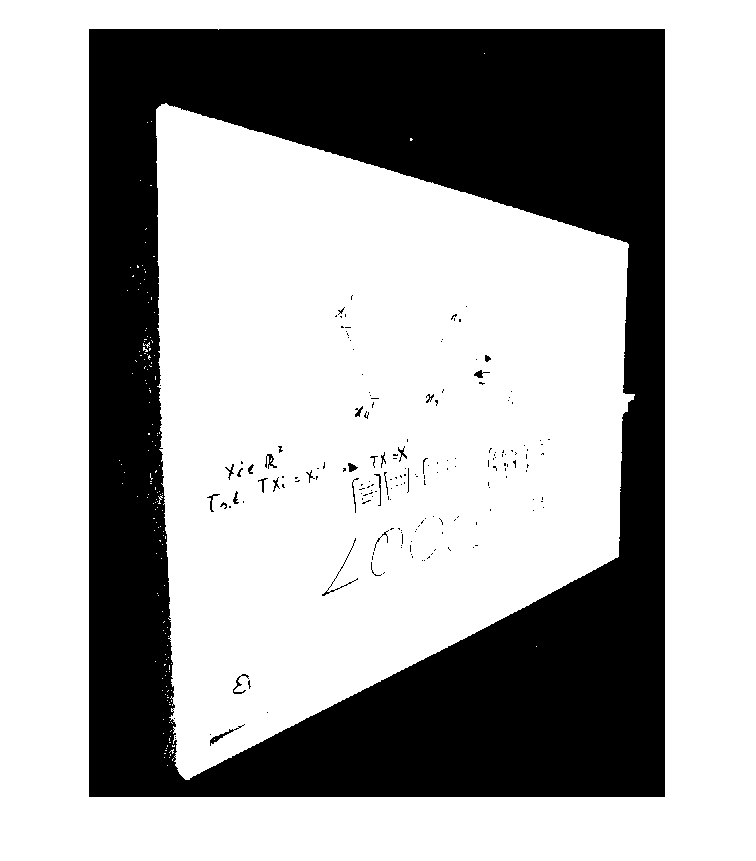

wb_bw = sum(wb,3)/3 > 50;
figure
imshow(wb_bw)

### Extract vertices

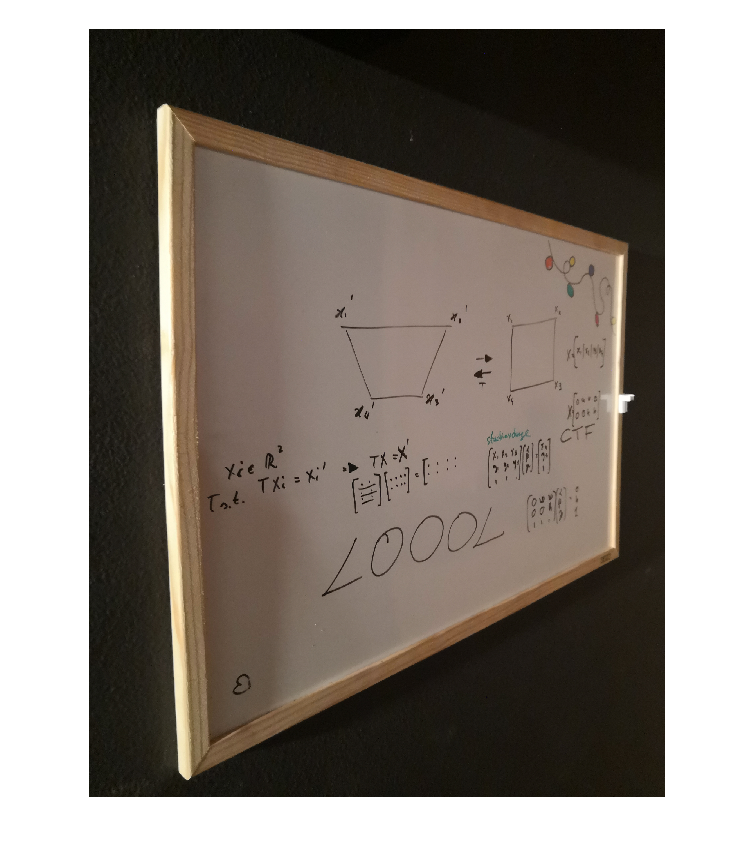

area =   Polygon with properties:

    Position: [4×2 double]
       Label: ''
       Color: [0 0.447000000000000 0.741000000000000]
      Parent: [1×1 Axes]
     Visible: on
    Selected: 0

  Show all properties


figure
% center = size(wb, [1 2])/2;
imshow(wb)
% pt = drawpoint
% pt = round(pt.Position)
% close gcf
% % bounds = bwtraceboundary(wb_bw,pt,'W') 
% hold on
% plot(contour(:,2),contour(:,1),'g','LineWidth',2)
area = drawpolygon

contour_pts = area.Position;
close gcf

## Process points

% [w, h] = deal(1920, 1280);
[w, h] = deal(1920*4, 1280*4);
% vector of destination vertex points
orig_pts = [[ 0 w w; 0 0 h ]; ones(1,3)]

orig_pts =            0        7680        7680
           0           0        5120
           1           1           1


orig_coeff = inv(orig_pts) * [ 0; h; 1];
A = orig_pts* diag(orig_coeff)

A =            0       -7680        7680
           0           0        5120
           1          -1           1


pts = [ round(contour_pts)'; ones(1,4)];
left = pts(:,1:3);
coeff = inv(left) * pts(:,4);
B = left* diag(coeff')

B = 	1.0e+03 *

   0.576002802504433  -6.213191534168685   6.361188731664249
   0.631565773807112  -2.674031799515636   6.324466025708523
   0.000926049521711  -0.001966199852585   0.002040150330874


A_1 = inv(A);
C = A/B

C = 	1.0e+02 *

   0.015507493236131  -0.000439378975024  -9.346004331907301
  -0.003828293214864   0.014330690529977  -7.392332561798854
  -0.000002208286675  -0.000000159253703   0.012280723908187


C = C'./C(3,3)

C = 	1.0e+02 *

   0.012627507427141  -0.003117318851466  -0.000001798173048
  -0.000357779377102   0.011669255523628  -0.000000129677781
  -7.610304084498194  -6.019459941502713   0.010000000000000


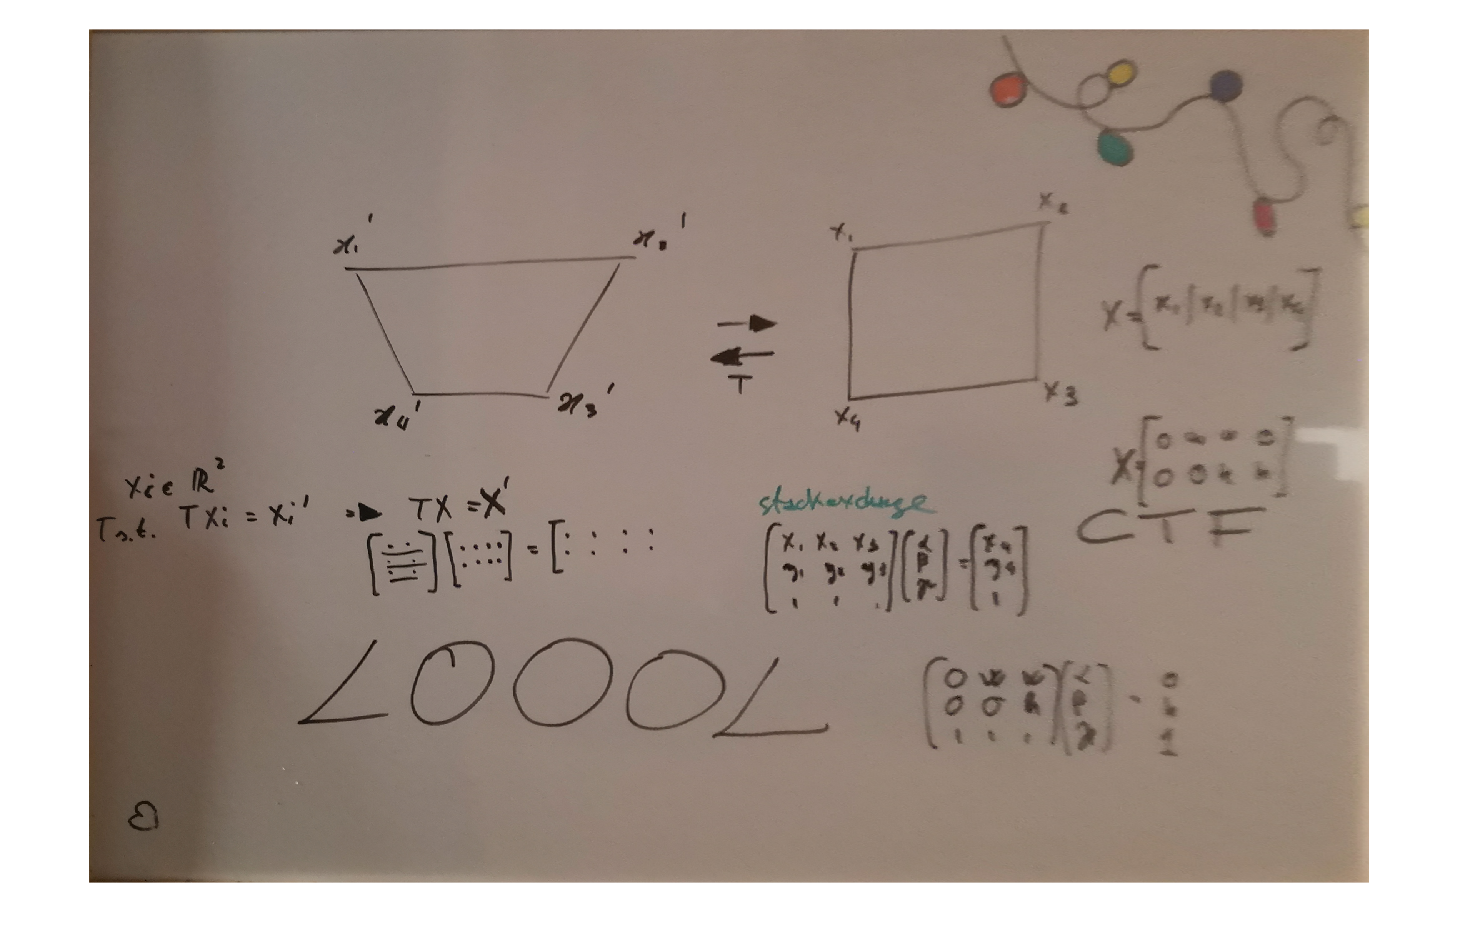

% C(1:2,3) = [0;0];
% C = [C(:,1:2) zeros(3,1) C(:,3)];
% C = [C(1:2,:); [0 0 1 0]; C(3,:) ]
% C1 = B*inv(A);
% C1 = C1' / C1(end,end)
% C1(1:2,end) = [0;0];

% C = [1 0.1 0; 0 1 0; 0 0 1]
tform = projective2d(C);
% sameAsInput = affineOutputView(size(A),tform,'BoundsStyle','SameAsInput');
sameAsInput = imref2d([h w]);
wb_new = imwarp(wb,tform,'OutputView',sameAsInput);
% imshow(wb_new)

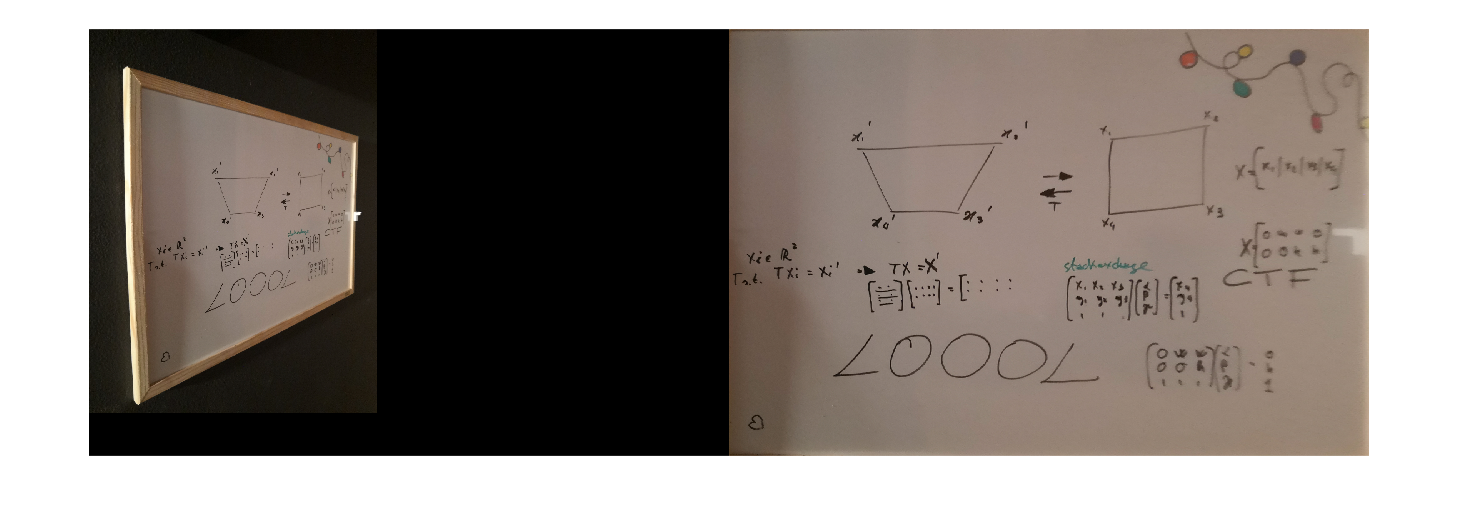

imshowpair(wb,wb_new,'montage')

% plot(contour(:,2),contour(:,1),'g','LineWidth',2)

0